# Inverse problems

## Calculated A

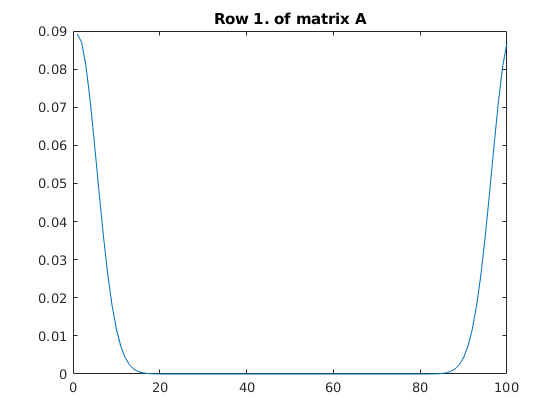

clearvars
clc
close all
ImportData

t = 0.001; % s
y = OppgA;
N = 100;
A = zeros(N,N);
for i = 1:N
    xi = (i-1)*(1/N);
    for j = 1:N
        xj = (j-1)*(1/N);
        dist = min(mod(xi-xj,1),mod(xj-xi,1)); % Modular distance
        A(i,j) = (1/(N*sqrt(4*pi*t)))*exp(-(dist^2)/(4*t));
    end
end
x=(0:N-1)*1/N;
figure
plot(A(1,:));
title("Row 1. of matrix A")

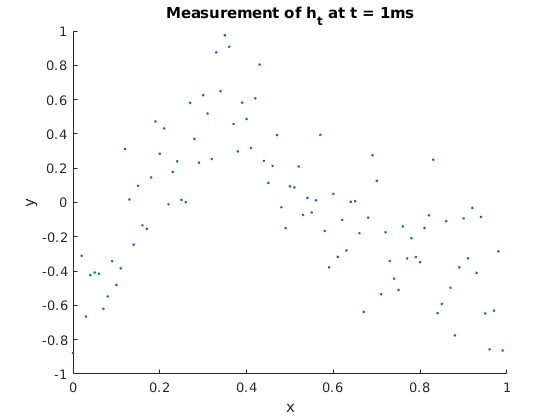


figure
scatter(x,y,".")
axis([0 1 -1 1])
ylabel("y");
xlabel("x");
title("Measurement of h_t at t = 1ms")

## Naive solution

h0 = A^(-1)*y;

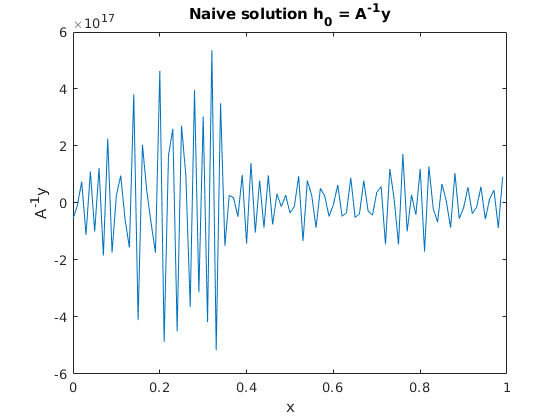

figure
plot(x,h0)
xlabel("x")
ylabel("A^{-1}y")
title("Naive solution h_0 = A^{-1}y")

## Eigenvalues

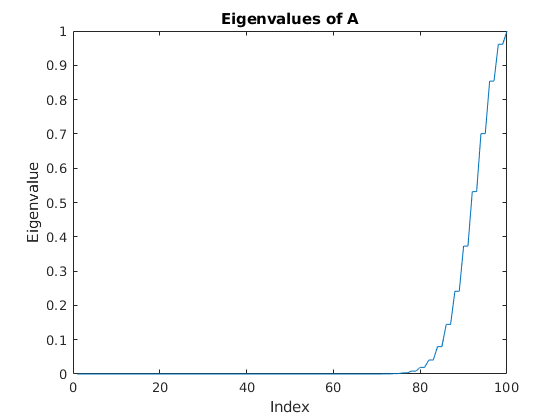

lambda = eig(A); % Reveresed order compared to svd()
figure
plot(lambda);
xlabel("Index");
ylabel("Eigenvalue");
title("Eigenvalues of A")

## Singular value decompesition

[U,S,V] = svd(A); % A == U*S*V'
% Should maybe calculated these manually from eigenvalues?
K = [5 10 15 20]; % Trunkation tresholds 
s = diag(S);
disp("Singular values of A")

Singular values of A


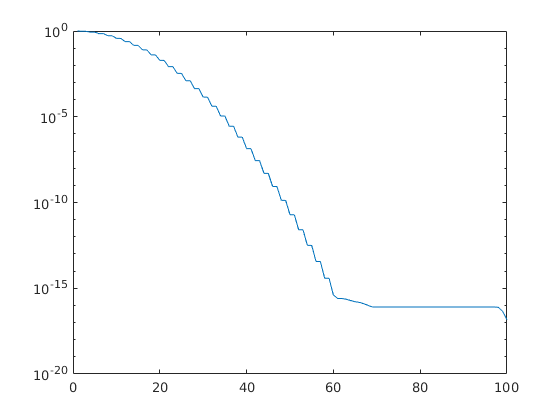

figure
semilogy(s)

%legend("Eigenvalues","Treshold")

disp("Truncated SVD solution")

Truncated SVD solution


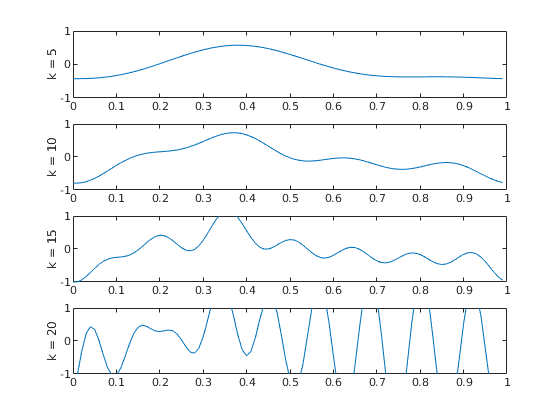

figure
plot_index =  1;
for k = K
    s_inv = s.^(-1);
    s_inv(k:end) = 0;
    S_inv = diag(s_inv);
    h0 = V*S_inv*U'*y;

    subplot(length(K),1,plot_index);
    plot_index = plot_index +1;
    plot(x,h0);
    axis([0 1 -1 1])
    ylabel(['k = ',num2str(k)])
    
end

## Gausian Prior

priorMean = 0;
priorCov = eye(100);
% From page 24, line 4 on the lecture notes, we see the distrobution of h_0 | y,  
% assumeing gausion measurment noise is given as f(x|y) = const* exp(-1/2[y-Ax)^T ...)
% Assuming this should also be a gauusian distrobution we can calculate E
% and var:

lambda = 1/(0.25^(-2)); % inversion parameter
likelihoodCov = eye(100)*0.25^2;

%h0 = ((A'*A + lambda*eye(N))^(-1))*A'*y;
sigma = (priorCov^(-1) + A'*likelihoodCov^(-1)*A)^(-1);
mu = sigma*A'*likelihoodCov^(-1)*y;
disp("Gausian MAP estimation using general identity prior")

Gausian MAP estimation using general identity prior


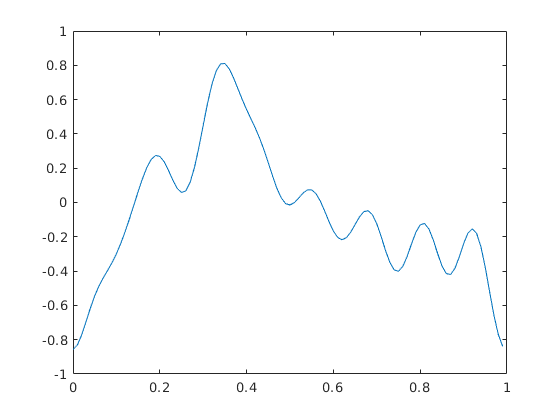

figure
plot(x,mu)
axis([0 1 -1 1])

## Smart prior

priorCov = zeros(N,N);
for i = 1:N
    xi = (i-1)*(1/N);
    for j = 1:N
        xj = (j-1)*(1/N);
        dist = min(mod(xi-xj,1),mod(xj-xi,1)); % Modular distance
        priorCov(i,j) = exp(-(dist)/(0.1));
    end
end

sigma = (priorCov^(-1) + A'*likelihoodCov^(-1)*A)^(-1);
mu = sigma*A'*likelihoodCov^(-1)*y;

disp("Gausian MAP estimation using problem spesific prior")

Gausian MAP estimation using problem spesific prior


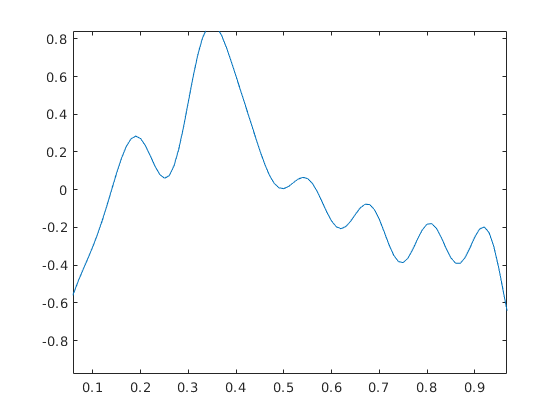

figure
plot(x,mu)
axis([0 1 -1 1])


%[x,xLo,xUp] = norminv([0.025 0.975],mu,sigma);

'norminv' requires Statistics and Machine Learning Toolbox.



%pd = makedist('Normal','mu',mu,'sigma',sigma)
                        
% yMean = mu;                                         % Mean Of All Experiments At Each Value Of ‘x’
% ySEM = diag(sigma)/sqrt(N);                         % Compute ‘Standard Error Of The Mean’ Of All Experiments At Each Value Of ‘x’
% CI95 = tinv([0.025 0.975], N-1);                    % Calculate 95% Probability Intervals Of t-Distribution
% yCI95 = bsxfun(@times, ySEM, CI95(:));              % Calculate 95% Confidence Intervals Of All Experiments At Each Value Of ‘x’
% figure
% plot(x, yMean)                                      % Plot Mean Of All Experiments
% hold on
% plot(x, yCI95+yMean)                                % Plot 95% Confidence Intervals Of All Experiments
% hold off
% grid


